# 测试

clc
clear
close all
addpath("src\");

n = 0.00111; % rad/s
tf = 2000.; % s
x0 = [-2200., -8000., 100., 0., 0., 0.]';  % m, m/s
step = 1;

[t, x] = CwIndirOpt(x0, n, tf, step);
% [t, x, lambda0] = CwDirOpt(x0, n, tf, step);

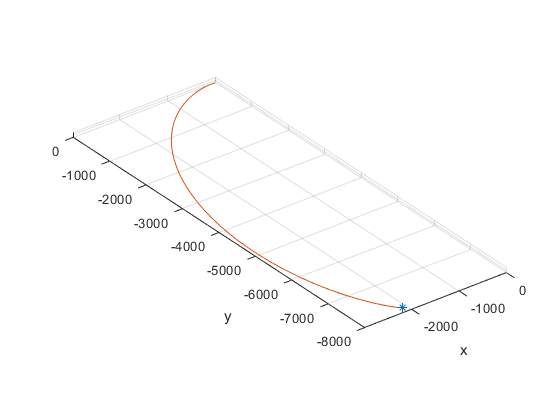

figure
plot3(x0(1), x0(2), x0(3), '*')
hold on
plot3(x(:, 1), x(:, 2), x(:, 3))
grid on
axis equal
xlabel('x')
ylabel('y')
zlabel('z')
hold on

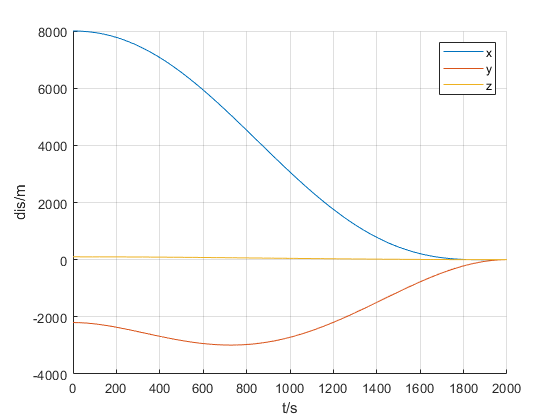

figure
hold on
plot(t, -x(:, 2))
plot(t, x(:, 1))
plot(t, x(:, 3))
grid on
legend('x', 'y', 'z')
xlabel('t/s')
ylabel('dis/m')
hold off

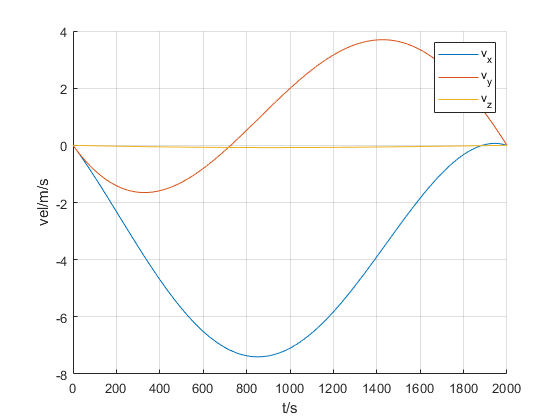

figure
hold on
plot(t, -x(:, 5))
plot(t, x(:, 4))
plot(t, x(:, 6))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

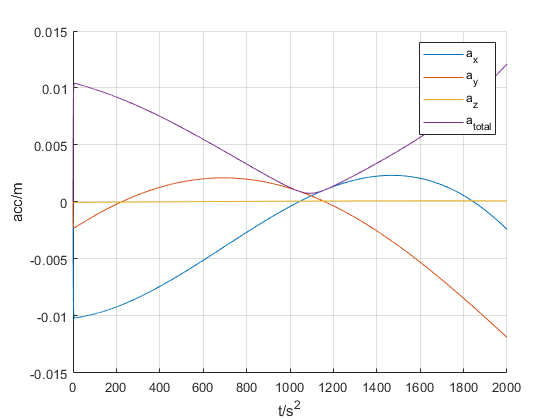

figure
hold on
plot(t, -x(:, 8))
plot(t, x(:, 7))
plot(t, x(:, 9))
a = zeros(length(t), 1);
for i = 1 : length(t)
    a(i) = norm(x(i, 7 : 9));
end
plot(t, a)
grid on
legend('a_x', 'a_y', 'a_z', 'a_{total}')
xlabel('t/s^2')
ylabel('acc/m')
hold off

sum(a) / length(t) * tf

ans = 11.3030